clc
clear all
syms x;
f1 = sinh(x)/x;
subplot(5,3, 1);
fplot(f1);
title('sinhx/x');

for i = 4:10
    func = f2(x,i);
    subplot(5, 3, i-2);
    fplot(func);
    str = sprintf('f2 for n=%d',i)
    title(str);
end

str = 'f2 for n=4'

str = 'f2 for n=5'

str = 'f2 for n=6'

str = 'f2 for n=7'

str = 'f2 for n=8'

str = 'f2 for n=9'

str = 'f2 for n=10'

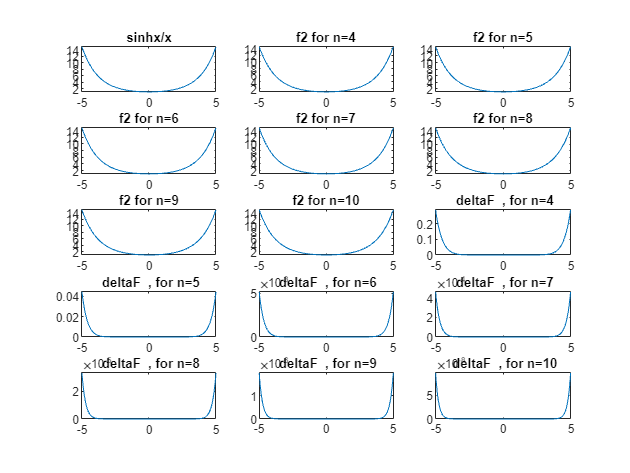

str = ' deltaF  , for n=4'

str = ' deltaF  , for n=5'

str = ' deltaF  , for n=6'

str = ' deltaF  , for n=7'

str = ' deltaF  , for n=8'

str = ' deltaF  , for n=9'

str = ' deltaF  , for n=10'


for i = 4:10
    deltaF = abs(f2(x,i) - f1);
    subplot(5, 3, i+5);
    fplot(deltaF);
    str = sprintf(' deltaF for n=%d',i)
    title(str);
end 

function [result] = f2(x,n)
    result = 0 ;
    for i=0:n
        result = result + ((x^(2*i))/(factorial((2*i)+1)));
    end
end